# INTERPOLACIÓ POLINOMIAL

## Interpolació

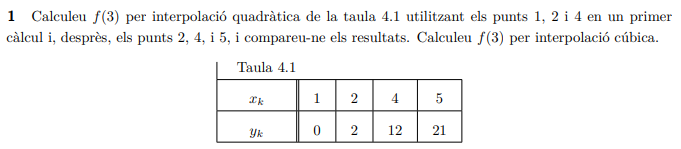

- primer càlcul

valor = polyinterp([1,2,4],[0, 2, 12],3); 
disp(['valor = ',num2str(valor)])

valor = 6


- segon  càlcul

valor = polyinterp([2,4,5],[2, 12, 21],3); 
disp(['valor = ',num2str(valor)])

valor = 5.6667


- tercer  càlcul

valor = polyinterp([1,2,4,5],[0, 2, 12, 21],3); 
disp(['valor = ',num2str(valor)])

valor = 5.8333


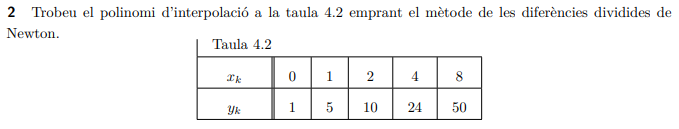

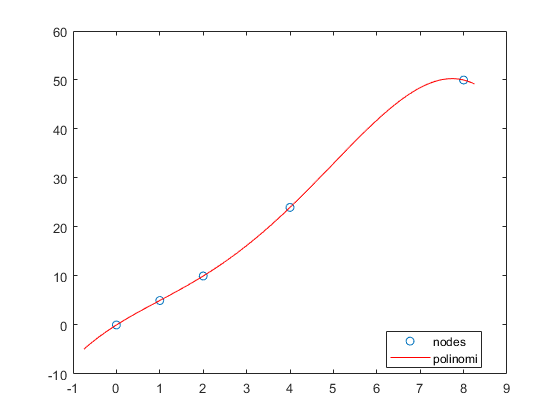

% ** No usant mètode Newton
x = [0 1 2 4 8]; y = [0 5 10 24 50];
u = -0.75:0.05:8.25;
v = polyinterp(x,y,u);
plot(x,y,'o',u,v,'r-'); legend('nodes','polinomi','Location','best')

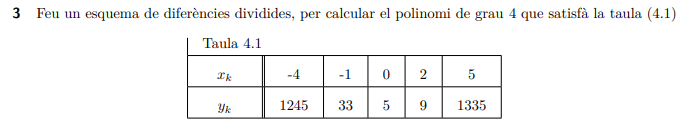

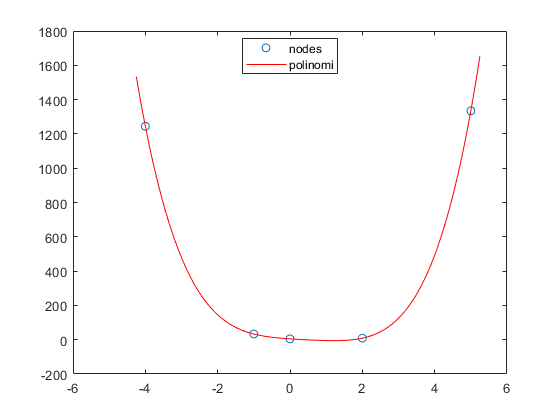

x = [-4 -1 0 2 5]; y = [1245 33 5 9 1335];
u = -4.25:0.05:5.25;
v = polyinterp(x,y,u);
plot(x,y,'o',u,v,'r-'); legend('nodes','polinomi','Location','best')

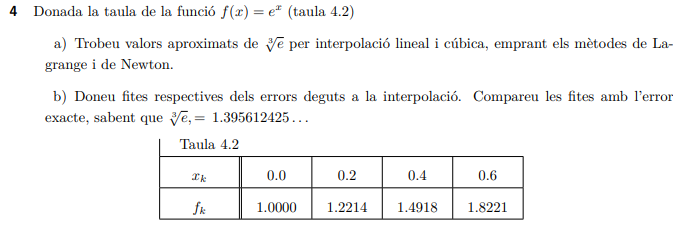

valor = exp(1/3);
x = [0 0.2 0.4 0.6]; y = exp(x);
% Interpolació lineal
x1 = [x(2) x(3)]; y1 = [y(2) y(3)];
valor_lineal = polyinterp(x1,y1,1/3), error = abs(valor_lineal-valor)

valor_lineal =        1.4017


error =     0.0060716


valor_cubica = polyinterp(x,y,1/3), error = abs(valor_cubica-valor)

valor_cubica =        1.3956


error =    4.4887e-05


f = @(x) x-exp(-x);
raiz = fzero(f,1)

raiz =       0.56714


xnodes = [0.50, 0.55, 0.60]';
ynodes = f(xnodes); disp([xnodes,ynodes])

          0.5     -0.10653
         0.55     -0.02695
          0.6     0.051188



arrel = polyinterp(ynodes,xnodes,0)

arrel =       0.56714


arrel = interp1(ynodes,xnodes,0,'pchip')

arrel =       0.56714


 p_arrel = polyfit(ynodes,xnodes,2); arrel = polyval(p_arrel,0)

arrel =       0.56714


r =        1.1257     0.057143


residu =       0.21044


r =         2.048      -8.4558       11.423        -5.12       1.0659      0.30286


residu =      0.097377


## D'examen 

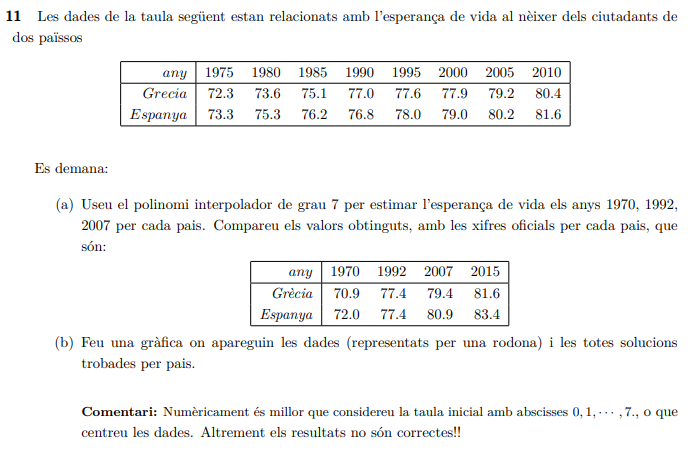

any = 1975:5:2010;
x = 1:8;
espanya = [73.3 75.3 76.2 76.8 78.0 79.0 80.2 81.6];
grecia = [72.3 73.6 75.1 77.0 77.6 77.9 79.2 80.4];
e1_1970 = polyinterp(x,espanya,0); er1_1970 = abs(72.0-e1_1970);
e1_1992 = polyinterp(x,espanya,4.4); er1_1992 = abs(77.4-e1_1992);
e1_2007 = polyinterp(x,espanya,7.4); er1_2007 = abs(80.9-e1_2007);


g1_1970 = polyinterp(x,grecia,0); gr1_1970 = abs(70.9-g1_1970);
g1_1992 = polyinterp(x,grecia,4.4); gr1_1992 = abs(77.4-g1_1992);
g1_2007 = polyinterp(x,grecia,7.4); gr1_2007 = abs(79.4-g1_2007);

R = [e1_1970, 72.0,er1_1970; e1_1992, 77.4, er1_1992; e1_2007, 80.9, er1_2007];
VarNames = {'estimació','oficial','error'};
T = array2table(R,'RowNames',{'1970','1992','2007'},'VariableNames',VarNames); 
fprintf('\n%21s\n\n', 'Esperança espanya'); disp(T)

    Esperança espanya

            estimació    oficial     error  
            _________    _______    ________
    1970       85.2         72          13.2
    1992     77.245       77.4       0.15518
    2007      80.98       80.9      0.080309


R = [g1_1970, 70.9, gr1_1970; g1_1992, 77.4, gr1_1992; g1_2007, 79.4, gr1_2007];
VarNames = {'estimació','oficial','error'};
T = array2table(R,'RowNames',{'1970','1992','2007'},'VariableNames',VarNames); 
fprintf('\n%21s\n\n', 'Esperança grecia'); disp(T)

     Esperança grecia

            estimació    oficial      error  
            _________    _______    _________
    1970       50.8       70.9           20.1
    1992     77.392       77.4      0.0078728
    2007     79.814       79.4        0.41436
